clear;      % Remove todas as variáveisa_wing_per_deg
clc;        % Limpa o console
close all;  % Fecha todas as janelas de figura
load('dados_estab+aero.mat')

## Contribuição da Asa-fuselagem p/ Estabilidade Lateral

A contribuição da asa é bem inferior se você considerar a asa como referência, entretanto a Fuselagem e outras estruturas como trem de pouso e Nacelles, em um caso geral, possuem efeito **DESESTABILIZANTE **para estabilidade direcional. Essa contribuição é calculada com o uso de dados Semi-Empíricos, ou seja, obter dados apartir de dados experimentais anteriores.

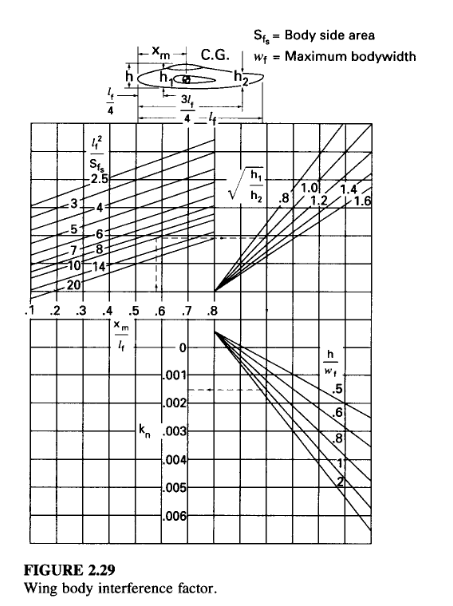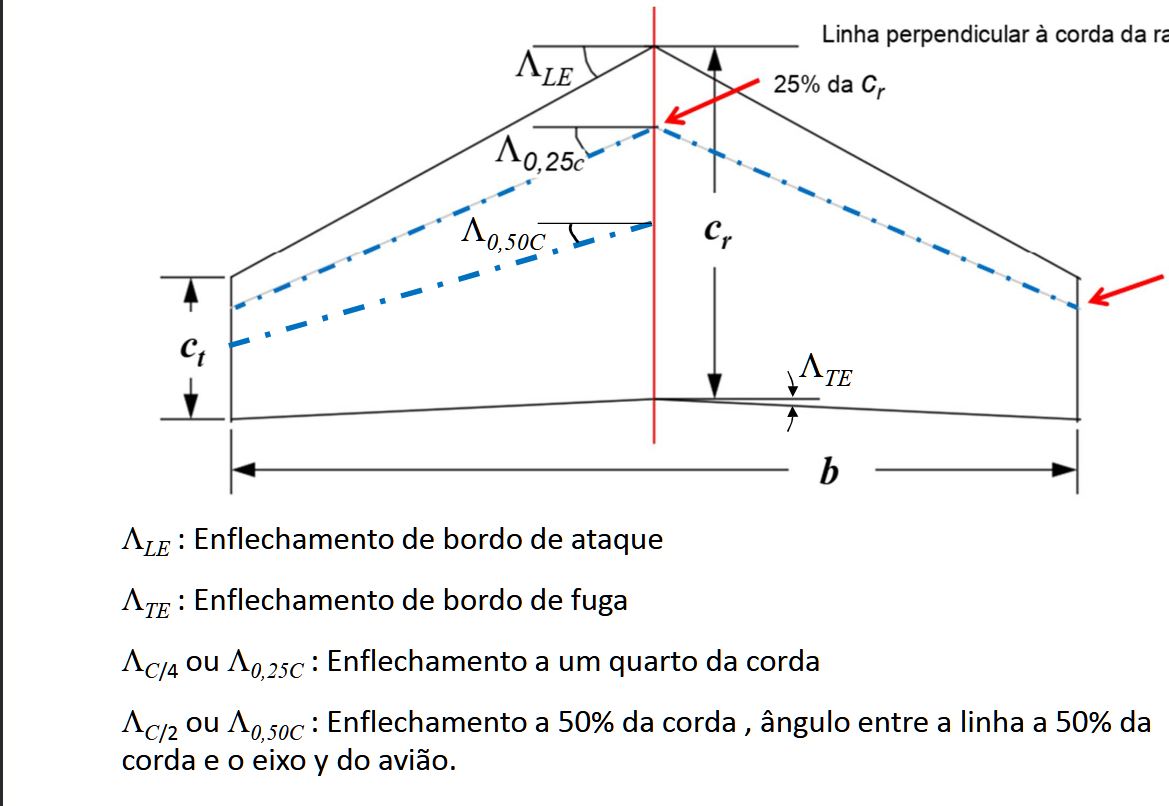

Embora já estejam bem definida a sua variação média no código, é bom ressalta-las mais uma vez. São dados empíricos:

- $K_n$ Fator de interferencia Asa-Fuselagem 


$$0,001\le K_n \le 0,005$$


- $K_{\textrm{Rl}}$ Fator de correção para o número de reynolds


$$K_{\textrm{Rl}} =1$$


%inputs fuselagem
Kn= 0.0025; %Fator Empirico - há relação com a geometria da fuselagem. Varia entre  0,001 < Kn < 0,005
kRL=1; %Variavel Empirica relacionada com o Numero de Reynolds da Fuselagem. 1 <= kRL <= 2,2
Sf=0.0357; %Area da fuselagem do plano Lateral
lF= 0.550; %comprimento da fuselagem
dF=0.093; % profundidade da fuselagem
CosA=1; %É o cosseno do ângulo de enflechamento da asa medido à 25% da corda da asa 
Zw=0.06; %altura projetada no eixo vertical da aeronave, entre o CG e o CA da Asa ( Linha da corda)
[cnbetawf]= contr_asafuse_vert(Kn, kRL, Sf, lF, Sw, bw);
fprintf('cnbetawf = %.10f\n', cnbetawf);

cnbetawf = -0.0000233427


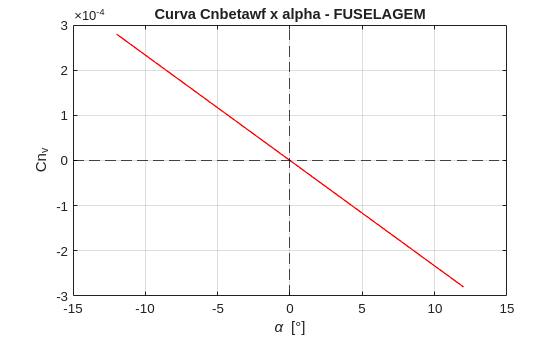

% 3. Plotagem
alpha_deg = linspace(-12, 12, 100); % Ângulo de ataque de -12 a 12 graus
Cmv = cnbetawf* alpha_deg;
figure;
plot(alpha_deg, Cmv, 'r-', 'LineWidth', 1);
grid on;
title('Curva Cnbetawf x alpha - FUSELAGEM');
xlabel('\alpha [°]');
ylabel('Cn_{v}');
xline(0, '--k');
yline(0, '--k');

## Contribuição da Empenagem Vertical p\ Estabilidade Lateral

Coeficiente Angular da curva do coeficeinte de sustentação em função do ângulo de ataque para o Estabilizador Vertical. Como já temos a Empenagem horizontal, ocorre um efeito de interferencia no Estabilizador vertical que toran essa superficie mais **EFICIENTE. **Vale ressaltar que, a partir de PHILLIPS sabemos que a empenagem vertical e a fuselagem tem um grande efeito na razãoo de aspecto aparente do Estabilizador Vertical, pois elas são como Winglets para o Estabilizador Vertical, aumento sua sustentação para um angulo de ataque. Os cálculos são trabalhosos, ja que que resolvi trabalhar com GUDMUSSON, PHILLIPS e ROSKAM a apartir da Teoria da linha de Prandtl.

%inputs empenagem vertical
clalphav = 0.07596363636; % coeficiente angular do perfil
Sv=0.036; %área da EV
lv=0.6; %Distancia do CG da aeronave ao CA da EV
ARv= 1; %razao de aspecto do ev
lambdav = 0.5;% afilamento
% 2. Parâmetros de Design
[Sv,crv,cpv, offset_tip,tan_LE, tang_c_2_v, bv, Clalphav,ARveff]=Geometria(Sv,ARv,lambdav, clalphav, Sh, ARh);
[Vv, Cnbetav, etah_v]=Contr_Est_Vert(Sv,lv, Sw, bw, ARw, Zw, dF, CosA, Clalphav, clalphav);

Vv = 0.0103

%Geometria
fprintf('clalphav = %f\n',clalphav)

clalphav = 0.075964


fprintf('Clalphav Metódo do Roskam e Philips= %f\n',Clalphav)

Clalphav Metódo do Roskam e Philips= 0.037982


fprintf('cnbetav = %f\n', Cnbetav);

cnbetav = 0.000850


fprintf('Sv = %.4f m^2\n', Sv);

Sv = 0.0360 m^2


fprintf('Razão de Aspecto do EV (ARv) = %f\n',ARv)

Razão de Aspecto do EV (ARv) = 1.000000


fprintf('Razão de Aspecto Efetiva(ARv) = %f\n',ARveff)

Razão de Aspecto Efetiva(ARv) = 15.274944


fprintf('Angulo de inclinação da reta do trapézio (Tan_LE) = %f\n',tan_LE)

Angulo de inclinação da reta do trapézio (Tan_LE) = 0.666667


fprintf('Angulo de inclinação da reta do trapézio da 2º seção (tang_c_2_v) = %f\n',tang_c_2_v)

Angulo de inclinação da reta do trapézio da 2º seção (tang_c_2_v) = 0.000000


fprintf('Afilamento do Ev (lambdav) = %f\n',lambdav)

Afilamento do Ev (lambdav) = 0.500000


fprintf('crv = %.4f m\n', crv);

crv = 0.2530 m


fprintf('cpv = %.4f m\n', cpv);

cpv = 0.1265 m


fprintf('bv = %.4f m\n', bv);

bv = 0.1897 m


[ev, Clalphav]=Nelson_method(ARv,clalphav);
fprintf('clalphav = %f\n',clalphav)

clalphav = 0.075964


fprintf('Clalphav Metódo do NELSON= %f\n',Clalphav)

Clalphav Metódo do NELSON= 0.024714


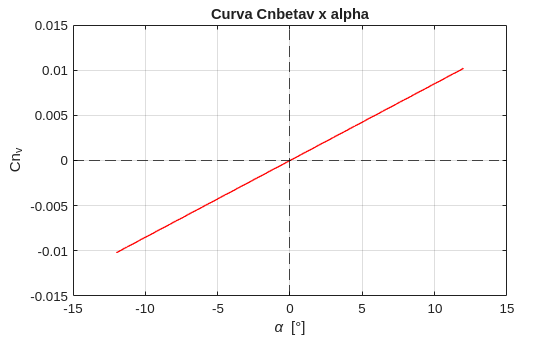

% 3. Plotagem
alpha_deg = linspace(-12, 12, 100); % Ângulo de ataque de -12 a 12 graus
Cmv = Cnbetav* alpha_deg;
figure;
plot(alpha_deg, Cmv, 'r-', 'LineWidth', 1);
grid on;
title('Curva Cnbetav x alpha');
xlabel('\alpha [°]');
ylabel('Cn_{v}');
xline(0, '--k');
yline(0, '--k');

## Contribuição da Aeronave completa c/ relação a Estabilidade Lateral

por roskam Cnbeta tem um nivel geral de 0.0010 1/deg

[cnbeta]=estab_dir_comp(Cnbetav, cnbetawf);

% 3. Plotagem
alpha_deg = linspace(-12, 12, 100); % Ângulo de ataque de -12 a 12 graus
cmv1 = cnbetawf* alpha_deg;
cmv2 = Cnbetav * alpha_deg;
cmv3 = cnbeta*alpha_deg;
fprintf('cnbeta = %f\n', cnbeta);

cnbeta = 0.000827


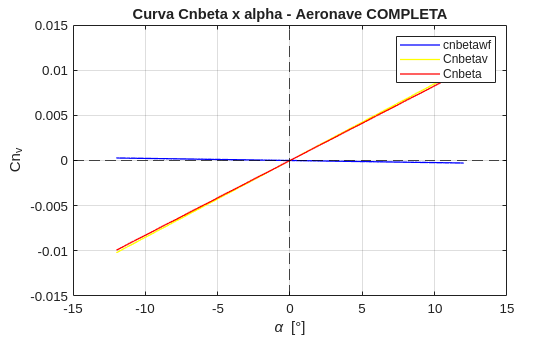

figure;
plot(alpha_deg, cmv1, 'b-', 'LineWidth', 1); % Primeira curva
hold on; % Mantém o gráfico para adicionar mais curvas
plot(alpha_deg, cmv2, 'y-', 'LineWidth', 1); % Segunda curva
plot(alpha_deg, cmv3, 'r-', 'LineWidth', 1); % Terceira curva

% Personalização do gráfico
grid on;
title('Curva Cnbeta x alpha - Aeronave COMPLETA');
xlabel('\alpha [°]');
ylabel('Cn_{v}');
xline(0, '--k'); % Linha vertical no zero
yline(0, '--k'); % Linha horizontal no zero
legend('cnbetawf', 'Cnbetav', 'Cnbeta'); % Legenda para diferenciar as curvas
hold off; % Finaliza a sobreposição de gráficos				


disp(table(Sv, Vv, bv, lv, 'VariableNames',{'Área do EV (m²)', 'Volume da de cauda EV', 'Envergadura do EV', 'braço do CA até o o CA do EV'}))

    Área do EV (m²)    Volume da de cauda EV    Envergadura do EV    braço do CA até o o CA do EV
    _______________    _____________________    _________________    ____________________________

         0.036               0.010271                0.18974                     0.6             



fprintf('  ')

fprintf('\n==================================================================================================================\n\n                                   ANÁLISE DE ESTABILIDADE VERTICAL ESTÁTICA');



                                   ANÁLISE DE ESTABILIDADE VERTICAL ESTÁTICA

fprintf('  ')

fprintf('  ')

## Funções

%função da Asa e fuselagem p/ estabilidade vetical
function [cnbetawf]= contr_asafuse_vert(Kn, kRL, Sf, lF, Sw, bw)
      cnbetawf = (-Kn*kRL*Sf*lF)/(Sw*bw);
end
%Função do estabilizador vertical		

%Geometria
function [Sv,crv,cpv, offset_tip,tan_LE, tang_c_2_v, bv, Clalphav, ARveff]=Geometria(Sv,ARv,lambdav, clalphav, Sh, ARh)

bv=sqrt(Sv*ARv); %envergadura
crv = Sv/((lambdav+1)*(bv/2)); %corda na ra iz
cpv = lambdav*crv; %corda na ponta
offset_tip = crv-cpv; % offset maximo
tan_LE = offset_tip/bv; % Angulo de inclinação da reta do trapézio
tang_c_2_v = tan_LE - (2/ARv)*((1-lambdav)/(1+lambdav));
% 3.2. Coeficiente Angular
% Figura 7.7. Roskan: Methods for Estimating Stability and Control Derivatives
kH = 0.176*((Sh/Sv)^3) - 0.8868*((Sh/Sv)^2) + 1.6361*(Sh/Sv) + 0.0018;

% 3.2.1. Razão de Aspecto Efetiva - [PHILLIPS: fig - 5.4.2]
if ARv <= 1.75
    ARveff_ARv = 0.0028*(ARh^5)-0.0372*(ARh^4)+0.1948*(ARh^3)-0.5196*(ARh^2)+0.7556*ARh+1.006;
elseif ARv > 1.75 && ARv <= 2
    ARveff_ARv = 0.0021*(ARh^5)-0.0287*(ARh^4)+0.1523*(ARh^3)-0.4131*(ARh^2)+0.6238*ARh+1.0044;
elseif ARv > 2 && ARv <= 2.25
    ARveff_ARv = 0.0018*(ARh^5)-0.0237*(ARh^4)+0.1259*(ARh^3)-0.343*(ARh^2)+0.5322*ARh+1.0055;
elseif ARv > 2.25 && ARv <= 3
    ARveff_ARv = 0.0015*(ARh^5)-0.0199*(ARh^4)+0.1072*(ARh^3)-0.2977*(ARh^2)+0.4744*ARh+1.0046;
elseif ARv > 3 && ARv <= 3.25
    ARveff_ARv = 0.0027*(ARh^5)-0.0313*(ARh^4)+0.1395*(ARh^3)-0.3198*(ARh^2)+0.4474*ARh+1.0068;
elseif ARv > 3.25 && ARv <= 4
    ARveff_ARv = 0.0024*(ARh^5)-0.0272*(ARh^4)+0.1229*(ARh^3)-0.2883*(ARh^2)+0.4123*ARh+1.0077;
end

ARveff = ARveff_ARv * ARv * (1 + kH*(ARveff_ARv - 1)); % AR effetivo se aumenta ou diminui pelo estabilizador horizontal
Aux_1 = (ARveff^2) / (((clalphav)/(2*pi))^2);
Aux_2 = (1 + tang_c_2_v^2);
Aux_3 = 2 * sqrt(Aux_1 * Aux_2 + 4); 

% Eq. 3.8. Roskan: Methods for Estimating Stability and Control Derivatives
Clalphav = 2*pi*ARveff/Aux_3;

end
function[ev, Clalphav]=Nelson_method(ARv,clalphav)
ev = 1 / (1 + 1 / (pi * ARv * (1.78 * (1 - 0.045 * exp(0.68) * log(ARv) - 0.64))));
 Clalphav = clalphav / (1 + (57.3 * clalphav / (pi * ARv * ev)));
end
function [Vv, Cnbetav, etah_v]=Contr_Est_Vert(Sv,lv, Sw, bw, ARw, Zw, dF, CosA, Clalphav,clalphav)
      Vv=(Sv*lv)/(Sw*bw)
      etah_v= 0.724+3.06*((Sv/Sw)/(1+CosA))+0.4*(Zw/dF)+0.009*ARw; %sidewash e eficiencia da empenagem vertical  
      Cnbetav = etah_v*Vv*clalphav; %% AVERIGUAR O CLAPHAH SE é perfil ou asa
end


function [Cnbeta]=estab_dir_comp(Cnbetav, cnbetawf)
    Cnbeta= Cnbetav + cnbetawf;
end




save('dados_estab+aero+dir.mat')

Cy_beta_v = -Clalphav * etah_v * (Sv / Sw);
K_f = 0.8;
Cy_beta_fus = -K_f * (Sf / Sw);
Cy_beta = Cy_beta_v + Cy_beta_fus

Cy_beta = -0.0316

%% Estimador de Peso com Base em Regressão Linear
% Este script estima o peso de uma nova empenagem (horizontal e vertical)
% usando apenas regressão linear.

%% Dados das Empenagens Anteriores
areas_h = [0.122, 0.089, 0.158, 0.195]; % Áreas das empenagens horizontais (m²)
pesos_h = [96.8, 88.49, 126, 134];    % Pesos das empenagens horizontais (g)

areas_v = [0.039, 0.08, 0.108];  % Áreas das empenagens verticais (m²)
pesos_v = [60, 64.85, 72.4,];     % Pesos das empenagens verticais (g)

%% Verificação dos Dados
disp('Dados das empenagens horizontais:');

Dados das empenagens horizontais:


disp(table(areas_h', pesos_h', 'VariableNames', {'Área (m²)', 'Peso (g)'}));

    Área (m²)    Peso (g)
    _________    ________

      0.122        96.8  
      0.089       88.49  
      0.158         126  
      0.195         134  




disp('Dados das empenagens verticais:');

Dados das empenagens verticais:


disp(table(areas_v', pesos_v', 'VariableNames', {'Área (m²)', 'Peso (g)'}));

    Área (m²)    Peso (g)
    _________    ________

      0.039          60  
       0.08       64.85  
      0.108        72.4  



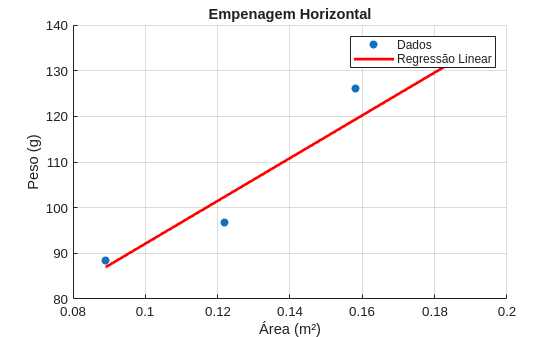


%% Ajuste de Modelos de Regressão
% Modelo linear para as empenagens
coef_h = polyfit(areas_h, pesos_h, 1); % Regressão linear (1º grau)
coef_v = polyfit(areas_v, pesos_v, 1); % Regressão linear (1º grau)

%Empenagem horizontal
figure; % Cria uma nova figura
scatter(areas_h, pesos_h, 'filled'); % Plota os pontos
hold on;
x_h = linspace(min(areas_h), max(areas_h), 100); % Define os valores de x para a linha
y_h = polyval(coef_h, x_h); % Calcula os valores de y usando o modelo ajustado
plot(x_h, y_h, 'r-', 'LineWidth', 2); % Plota a linha de regressão
title('Empenagem Horizontal');
xlabel('Área (m²)');
ylabel('Peso (g)');
grid on;
legend('Dados', 'Regressão Linear');

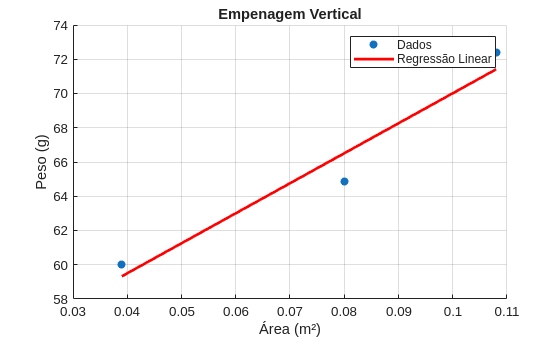


% Empenagem vertical
figure; % Cria uma nova figura
scatter(areas_v, pesos_v, 'filled'); % Plota os pontos
hold on;
x_v = linspace(min(areas_v), max(areas_v), 100); % Define os valores de x para a linha
y_v = polyval(coef_v, x_v); % Calcula os valores de y usando o modelo ajustado
plot(x_v, y_v, 'r-', 'LineWidth', 2); % Plota a linha de regressão
title('Empenagem Vertical');
xlabel('Área (m²)');
ylabel('Peso (g)');
grid on;
legend('Dados', 'Regressão Linear');

## Parâmetros da Nova Empenagem para Estimativa



fprintf('Sh da nova: %.5f g\n', Sh);

Sh da nova: 0.22756 g


fprintf('Sv da nova: %.5f g\n', Sv);

Sv da nova: 0.03600 g



%% Estimativa do Peso
% Cálculo do peso estimado com base nos modelos ajustados
peso_horizontal = polyval(coef_h, Sh);
peso_vertical = polyval(coef_v, Sv);

%% Análise de Resíduos
% Resíduos para empenagem vertical
pesos_v_previstos = polyval(coef_v, areas_v);
residuos_v = pesos_v - pesos_v_previstos;

%% Resultados
% Exibição do peso estimado
fprintf('Peso estimado da empenagem horizontal: %.2f g\n', peso_horizontal);

Peso estimado da empenagem horizontal: 151.87 g


fprintf('Peso estimado da empenagem vertical: %.2f g\n', peso_vertical);

Peso estimado da empenagem vertical: 58.80 g


fprintf('Peso total estimado (horizontal + vertical): %.2f g\n', peso_horizontal + peso_vertical);

Peso total estimado (horizontal + vertical): 210.67 g



% Exibição da análise de resíduos
disp('Resíduos (vertical):');

Resíduos (vertical):


disp(table(areas_v', pesos_v', pesos_v_previstos', residuos_v', ...
    'VariableNames', {'Área (m²)', 'Peso Real (g)', 'Peso Previsto (g)', 'Resíduo (g)'}));

    Área (m²)    Peso Real (g)    Peso Previsto (g)    Resíduo (g)
    _________    _____________    _________________    ___________

      0.039             60             59.327            0.67326  
       0.08          64.85             66.509            -1.6591  
      0.108           72.4             71.414            0.98585  



save('limitacao_motor.mat')

## LIMITACAO 2025

[p,d2,peso_motor,d1,x,dtotal,Ajmotor]=lim_2025(lh,peso_horizontal,lv, peso_vertical, Sh,bh,bw);

d1 = 0.167360


fprintf('ajsute: %.3f m\n', Ajmotor);

ajsute: 0.106 m


fprintf('total: %.3f m\n', dtotal);

total: 3.394 m


function [p1,d2,p2,d1,x,dtotal,Ajmotor]=lim_2025(lh,peso_horizontal,lv, peso_vertical, Sh,bh,bw);
  p1=416.1; %Peso do motor (g)
   d2= 0.12; %Distancia do CG da aeronave ate os componentes eletrico (m)
   p2=961; %Peso dos componentes eletricos
   p3 = 32; %Peso dos serves do EH e EV (g)
   d1=((-p2*d2)+(lh*(peso_horizontal+p3))+(lv*(p3+peso_vertical)))/p1; %Distancia do CG da Aeronave ate o CG do motor
      fprintf('d1 = %f\n', d1);

      
   x= 0.75*(Sh/bh)+lh+ d1; %distantcia do motor ate o profundor
   dtotal= x + bw; % Calculo do Edital 
   Ajmotor= 3.5 - dtotal;
end
save('finalizado.mat')